% 同一通道，每一个时间点，两种刺激之间的配对样本t检验

% data path
data_path = 'D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared';

% 定义一个对象用于存放不同marker信息
% 'CS+：112'
% 'GS1：113'
% 'GS2：114'
% 'GS3：115'
% 'GS4：116'
% 'GS5：117'
% 'GS6：118'
% 'GS7：119'
% 'GS8：120'
% 'CS-：121'
cond = {'112','113','114','115','116','117','118','119','120','121'};

% 将每个被试平均后的数据【分不同条件】合成一个数据集
for i = 1:4
    try
        % 拼接被试的文件名
        data_name = ['sub',num2str(i),'.set'];
        % 导入该被试数据
        EEG = pop_loadset('filename',data_name,'filepath',data_path);
        % 检查EEG数据是否完好
        EEG = eeg_checkset(EEG);
        for j = 1: length(cond)% 对于每个条件下的tiral
            EEG_new = pop_epoch(EEG,cond(j),[-1,2],'newname','sub_cond_lv_data','epochinfo','yes');
            EEG_new = eeg_checkset(EEG_new);
            % 基线矫正
            EEG_new = pop_rmbase(EEG_new,[-1000 0]);
            EEG_new = eeg_checkset(EEG_new);
            % EEG_new.data是一个三维数据集：channel × timepoint × trial
            % 做trial水平上的均值，降维，得到二维数据集，然后添加被试变量i，条件变量j，组成四维数据集
            % EEG_avg：subject × condition × channel × timepoint
            EEG_avg(i,j,:,:) = squeeze(mean(EEG_new.data,3));
        end
    catch ME
    end
end

pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub1.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():41 epochs selected
Epoching...
pop_epoch():41 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():17 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():16 epochs selected
Epoching...
pop_epoch():16 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():17 epochs selected
Epoching...
pop_epoch():16 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():16 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():41 epochs selected
Epoching...
pop_epoch():36 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub2.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():21 epochs selected
Epoching...
pop_epoch():21 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub3.set ...
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub4.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():17 epochs selected
Epoching...
pop_epoch():16 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():10 epochs selected
Epoching...
pop_epoch():10 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():9 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():11 epochs selected
Epoching...
pop_epoch():10 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():13 epochs selected
Epoching...
pop_epoch():11 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():22 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


% 选取一个电极点，这里以AF4为例子
data_test = squeeze(EEG_avg(:,:,5,:));

%创建一个cell用于储存t检验的数据
t_sts = {};

% 对于每一个时间点：
for i = 1:size(data_test,3)
    % data_test：subject × condition × timepoint
    % 提取所有被试，csp和csm条件下的第i个时间点的数据
    data1 = EEG_avg(:,1,i); % 1-csp
    data2 = EEG_avg(:,10,i); %10-csm
    
    % 输入两个条件的数据，输出4个结果，按顺序从左到右
    % [h,p,ci,stats]
    % h-是否拒绝零假设，值0-1，0表示无法拒绝，即不显著。
    % p-就是p值
    % ci-置信区间
    % stats-是一个结构体（struct），包含三个东西：T值，df值，sd值（标准差）
    [sig,p,~,stats] = ttest(data1,data2);
    
    % 创建一个cell储存t检验参数
    t_sts{i} = stats; 
    % 创建一个数组单独储存p值，用于后续的绘图
    p_value(i) = p;
end

clear data1 data2 sig p stats i j ME

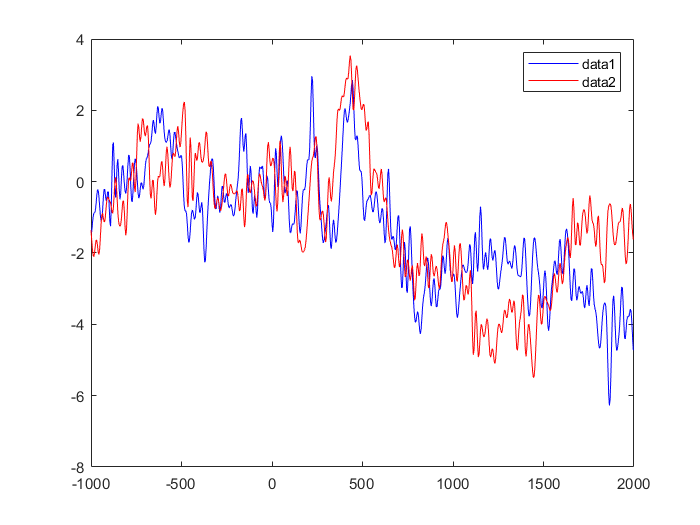

% 画出两种刺激的erp图，并且标明它们之间有显著差异的时间点
% 空白画布
figure;

% 2行1列第一张，两种刺激的ERP
% data_test：subject × condition × timepoint
plot(EEG.times,squeeze(mean(data_test(:,1,:),1)),'b');
hold on;
plot(EEG.times,squeeze(mean(data_test(:,10,:),1)),'r');
hold off;

% 图例
legend();

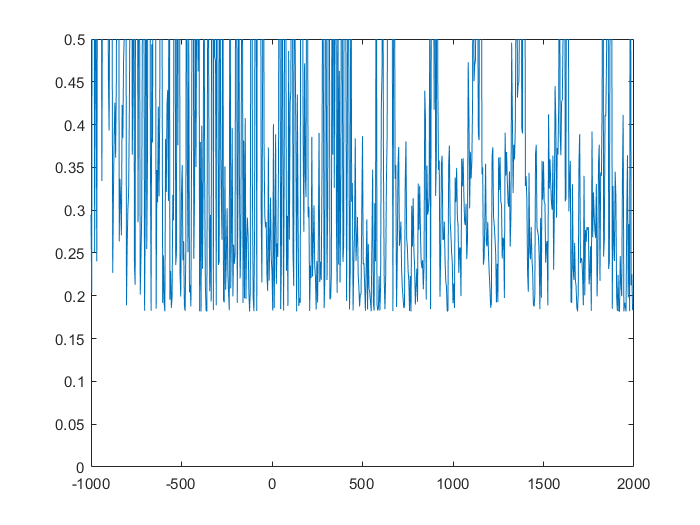


% 2行1列第2张，画出p值小于0.05的时间点
plot(EEG.times,p_value);
ylim([0 0.5]);


% 找到显著的采样点位置信息
sig_idx = find(p_value<0.05);

% 找到有显著差异的时间点
sig_timepoint = EEG.times(sig_idx);